
slice = 512;

rng(1)

ds = load('LabledData\raw_labled.mat', 'ls');
ds = ds.ls.Labels;
lables = ds.detect_blinks;
dir = ds.Properties.RowNames;

fs = 512;

downsampleRate = 4;


Ds = {};
for i = 1:numel(dir)    
    raw_data = csvread(dir{i},1,1);
    data = hl_filter(raw_data(:,1),true);%raw_data(:,1)is Fp1
    
%     %%%%%%%%% fft
%     stft(data,fs,'FrequencyRange','onesided')
%     t_data = stft(data,fs,'FrequencyRange','onesided');
%     t_data = t_data(size(t_data,1)-channel+1:size(t_data,1),:);
%     sample = floor(size(data,1)/size(t_data,2));
%     %%%%%%%%%fft

    r_data = [];
    lable = [];    
    masked = getmask({data,lables{i,1}});
%     %%%%%%fft
%     for j=1:size(t_data,2)
%         r_data = [r_data; data(1+(j-1)*sample)];
%         lable = [lable; masked{2}(1+(j-1)*sample)];
%     end
%     %%%%%%fft
    %%%%%%downsample
    d_data = downsample(data,downsampleRate);
    d_mask = downsample(masked{2},downsampleRate);
    Ds{i} = {d_data,d_mask};  
end


signalLength = slice;
chopedDs = {};

for i = 1:numel(Ds)
    firstNameLength = length(num2str(numel(Ds)));
    for j = 1:slice-1:numel(Ds{1,i}{1,1}(:,1))-slice-1
        secondNameLength = length(num2str(numel(Ds{1,i}{1,1}(:,1))-slice-1));
        signalLength = slice;
        data = Ds{1,i}{1,1}(j:j+slice-1,:);
        fb = cwtfilterbank('SignalLength',signalLength,'VoicesPerOctave', 48, ...
            'SamplingFrequency', fs/downsampleRate,'FrequencyLimits', [0.3333 4]);        
        [cfs, frq] = fb.wt(data);
        acfs = abs(cfs);
        acfs = acfs - min(min(acfs));
        th = quantile(acfs(:) , 0.975);
        acfs(acfs(:) > th) = th;
        acfs = acfs/th;
        t_data = im2uint8(acfs);

        chopedDs{end+1} = {t_data,Ds{1,i}{1,2}(j:j+slice-1)'};        
    end
end



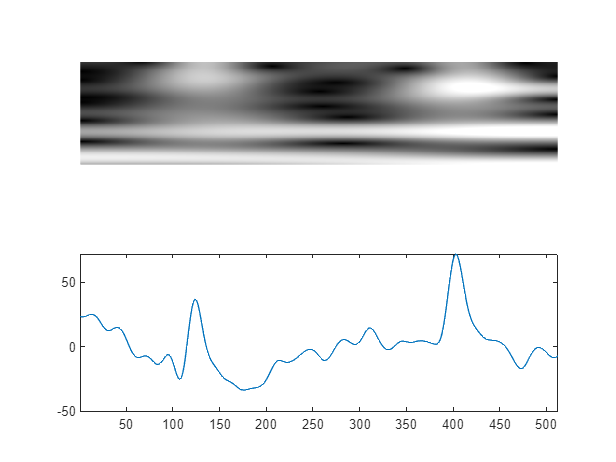

for i=14
    figure
    subplot(2,1,1)
    imshow(chopedDs{1, i}{1, 1}  )
    subplot(2,1,2)
    plot(Ds{1,1}{1,1}(1+(i-1)*slice:slice+(i-1)*slice,:))
    xlim([1 slice])
end

XTrain = {};
YTrain = {};
summarize = {};

pieceSize = [size(chopedDs{1}{1}) 1 1];
XTrainArray = ones(pieceSize);

for i = 1:numel(chopedDs)
    XPiece={};
    for j = 1:slice
        XPiece{end+1} = chopedDs{i}{1}(:,j);
    end
    XTrainArray = cat(4,XTrainArray,reshape(chopedDs{i}{1},pieceSize));
    XTrain{end+1,1} = chopedDs{i}{1};
    YTrain{end+1,1} = chopedDs{i}{2};
    if sum(YTrain{end} == "blink") > 0
        summarize{end+1} = "blink";
    else
        summarize{end+1} = "n/a";
    end
end
XTrainArray = XTrainArray(:,:,:,2:end);
% allImgs = imageDatastore('WtImg\','FileExtensions','.jpg');




[trainIdx,~,testIdx] = dividerand(numel(XTrain),0.7,0,0.3);

XTest = XTrain(testIdx);
YTest = YTrain(testIdx);
XTrain = XTrain(trainIdx);
YTrain = YTrain(trainIdx);

% 
% imgTrain = allImgs.subset(trainIdx);
% imgTest = allImgs.subset(testIdx);
i=1;
XT = reshape(chopedDs{i}{1},[size(chopedDs{i}{1},1) size(chopedDs{i}{1},2) 1 1]);
YT = [];
PY = reshape(chopedDs{i}{2},[1 size(chopedDs{i}{1},2) 1 1]);
simpleY = reshape(chopedDs{i}{2},[size(chopedDs{i}{1},2) 1]);
for i = 1:numel(chopedDs)
    XT = cat(4,XT,reshape(chopedDs{i}{1},[size(chopedDs{i}{1},1) size(chopedDs{i}{1},2) 1 1]));
    YT = [YT; chopedDs{i}{2}];
    PY = cat(4,PY,reshape(chopedDs{i}{2},[1 size(chopedDs{i}{1},2) 1 1]));
    simpleY = [simpleY, reshape(chopedDs{i}{2},[size(chopedDs{i}{1},2) 1])];
end



dataClassNames = ["blink","n/a", "muscle-artifact"];
pixelLabelIds = 1:numel(dataClassNames);
classNames = ["blink","noBlink", "muscleArtifact"];
imds = imageDatastore(fullfile('8604','WtImg'),FileExtensions=".jpg");
pxds = pixelLabelDatastore(fullfile('8604','PixelLableImg'),classNames,pixelLabelIds);

imdsTrain = imds.subset(trainIdx);
pxdsTrain = pxds.subset(trainIdx);

dsTrain = combine(imdsTrain,pxdsTrain);


imdsTest = imds.subset(testIdx);
pxdsTest = pxds.subset(testIdx);
testImgSize = [size(imread(imdsTest.Files{1,1})) 1 1];
imgsTest = ones(testImgSize);

for i =1:numel(imds.subset(testIdx).Files)
    imgsTest = cat(4,imgsTest,reshape(imread(imds.subset(testIdx).Files{i,1}), testImgSize));
end
imgsTest=imgsTest(:,:,:,2:end);


TY = [];
for i = 1:numel(YTest)       
    YPiece = YTest{i,1};
    YPiece(YPiece=='muscle-artifact') = 'muscleArtifact';
    YPiece(YPiece=='no-blink') = 'noBlink';
    YPiece(YPiece=='n/a') = 'noBlink';
    TY = [TY;YPiece];
end
dsTest = {TY,imgsTest};

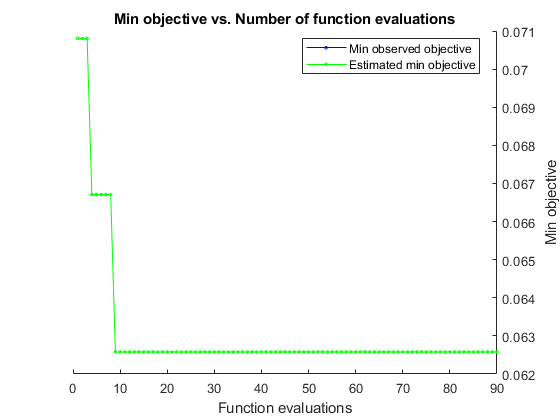

maxEpochs = 30;
optimVars = [
    %numBlocks,filterSizeC,filterSizeS, filterNum, dropoutLayerRegularization
    optimizableVariable('numBlocks',[1 8],'Type','integer')
    optimizableVariable('numFilters',[2 32],'Type','integer')
    optimizableVariable('filterSizeC',[1 32],'Type','integer')
    optimizableVariable('filterSizeS',[1 32],'Type','integer')
    optimizableVariable('filterNum',[1 16],'Type','integer')
    optimizableVariable('dropoutLayerRegularization',[0.00 0.2],'Type','real')
    optimizableVariable('learningrate',[1e-5 1e-1],'Type','real',"Transform","log")];

    objectFunction = objectFunctionCNN(dsTrain, dsTest,  maxEpochs);
    
% optimizer
BayesObject = bayesopt(objectFunction, optimVars, ...
    'MaxTime',10*60*60, ...
    'Verbose',0,...
    "UseParallel",false,...
    'IsObjectiveDeterministic',true, ...
    'ParallelMethod',"clipped-model-prediction",...
    'MaxObjectiveEvaluations',90,...
    'ExplorationRatio',0.6,...
    'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);

save("8604\hyperParameter\CNN_0.mat","optVars","-mat");

    % Evaluate and train the network with the optimal parameters
% [valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

TX = {};
for i = 1:numel(testDs)
    TX{end+1} = testDs{i}{1};
end

Unrecognized function or variable 'testDs'.



TY = [];
Y = [];
YTest = YTest.';
for i = 1:numel(testDs)
    TY = [TY;YTest{i}];
    Y = [Y;YPred{i}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized');

optVars = bestPoint(BayesObject);

save("8604\hyperParameter\TCN_0.mat","optVars","-mat");
